# *Assignment 2 -- Local Operations*

*Image and Video Processing*

## Ground Rules for the Assignment

- You can only use basic functions (matrix operations, input/output image functions, plotters). Anything else, you need to code from scratch (histogram functions, inverting gamma functions, color matting, histogram equalization).

- The code needs to be appropriately commented and should be reproducible; if we cannot re-generate your figures from your code, we will deduct points.

- The Live Script Report should be detailed and include partial and final soltuions for each exercise. We grade solely the `Report` part; code without report will not be graded, so we encourage that you invest some time on it.

- Interactive plots are welcome, but most important results should be static and generated beforehand.

- Remember to remove all plots and output from the `Task` sections. Only the `Report` should output plots and/or images.

## Submission Details

Simply submit this Live Script with the report inlined as described below. Name the file as `surname1_name1_surname2_name2_assignment1.mlx`

## 1. Linear Motion Blur Filter [7 Points]

The Gaussian kernels you have seen in the lecture are radially symmetric, i.e., isotropic. One can make Gaussian filters directional, i.e., anisotropic, by defining standard deviations separately for horizontal and vertical directions. More precisely, given two standard deviations $\sigma_x$ and $\sigma_y$ for the horizontal and vertical direction, respectively, the anisotropic Gaussian is defined by:

$G(x,y) = A\cdot e^{-\left(\frac{x^2}{2\sigma_x^2}+\frac{y^2}{2\sigma_y^2}\right)}$,

where $A$ is the normalizing coefficient that makes the weights sum up to 1. 

Additionally, we can rotate the Gaussian function by angle $\theta$ by applying rotation to the coordinates of the kernel. In practice, you define your rotated Gaussian as:

$G(x,y) = A\cdot e^{-\left(\frac{x_\theta^2}{2\sigma_x^2}+\frac{y_\theta^2}{2\sigma_y^2}\right)}$,

where


$$x_\theta = x \cdot cos(\theta) - y \cdot sin(\theta)$$



$$y_\theta = x \cdot sin(\theta) + y \cdot cos(\theta).$$


**Task.** In this exercise, you will simulate a motion blur with the anisotropic Gaussian filter. The idea is to filter an image with a Gaussian filter which is oriented along the motion direction. To this end:

- Implement a function that computes an anisotropic Gaussian kernel for blurring the image along the motion direction. The function should take as an input the angle of motion ($\theta$), $\sigma_x$, and $\sigma_y$. 

- Apply this filter to the provided `graz.png` image to simulate motion blur at an angle of 45 degrees, as shown in the Figure 1b. Experiment with parameters $\sigma_x$ and $\sigma_y$ to obtain the results you like. Include the resulting image and the filter in the report, similarly as demonstrated in the Figure 1b. You can use the `conv2 `function for this exercise.

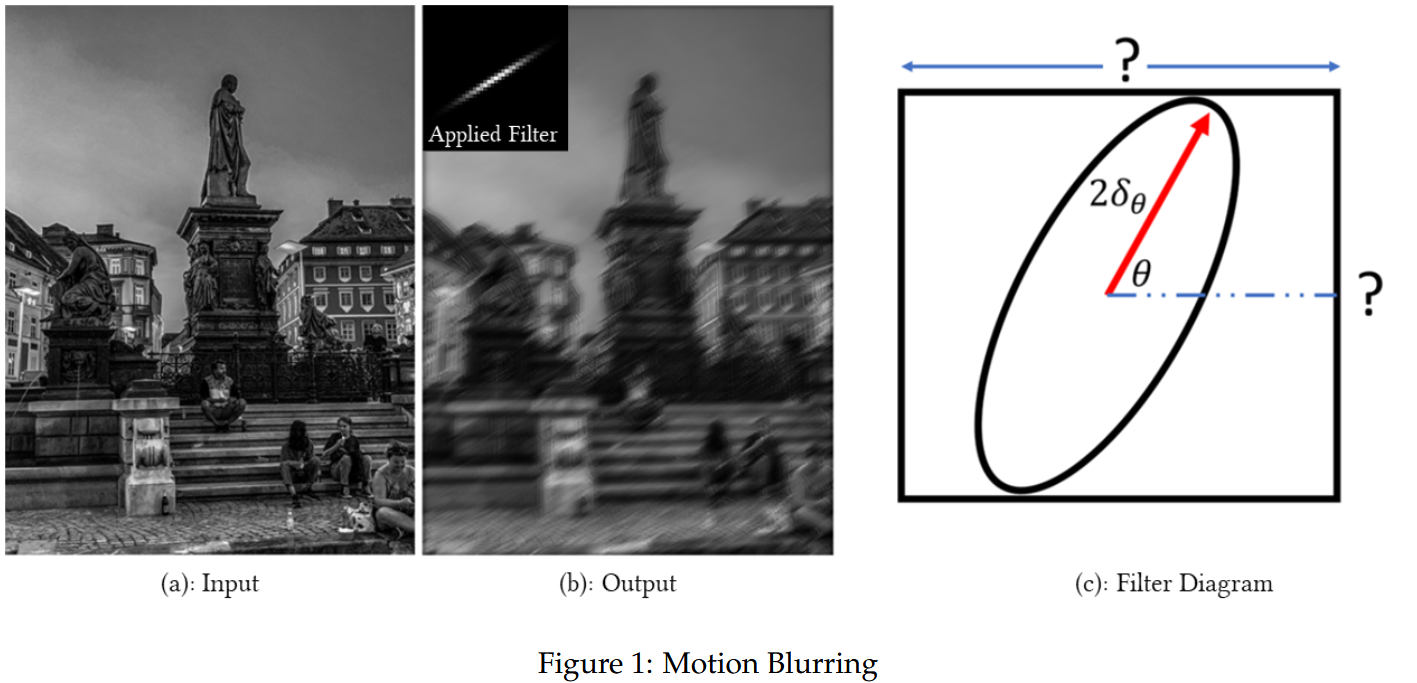

% Add your code here. 
% You can include comments in your code explaining the steps of your algorithm.

**Report. ***Add your report here.*

% Inline your images here.

*... Add your report here.*

## 2. Iterative Filtering [6 Points]

Applying a Gaussian filter to an image multiple times results in a similar result to applying one bigger Gaussian filter; see Figure 2. Verify empirically to what extent this is true also for a bilateral filter. For the experiments, you can use the implementation of the bilateral filter provided in MATLAB (`imbilatfilt`). Note that the two parameters of this function (`DegreeOfSmoothing` and `SpatialSigma`) correspond to standard deviation parameters of range and domain kernels discussed during the lecture. 

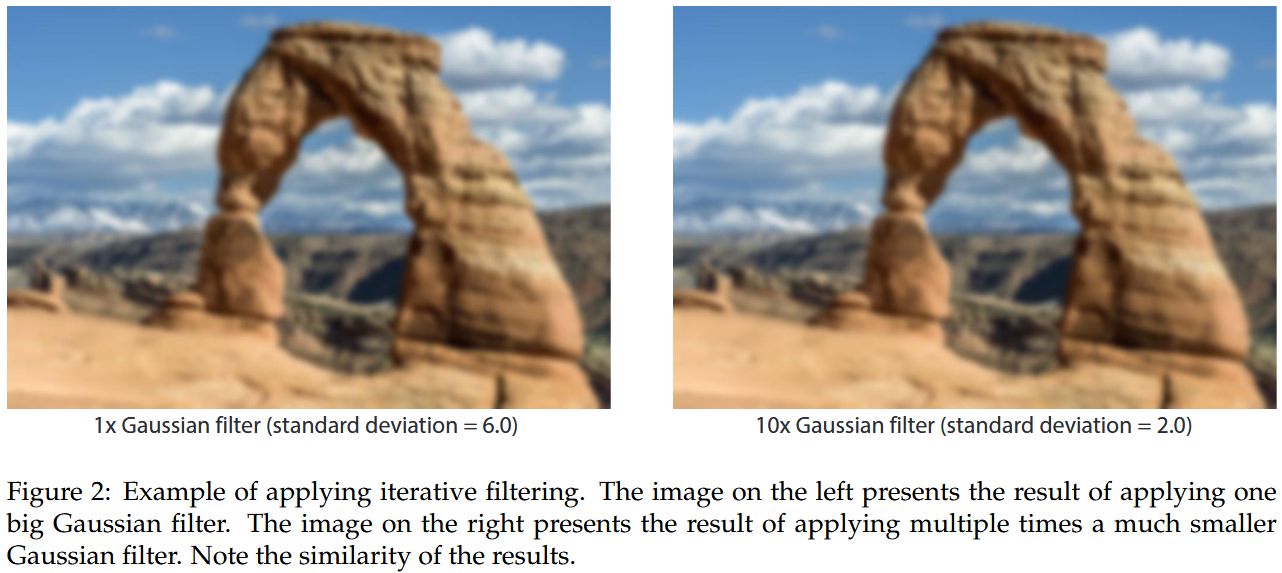

**Task. **Present the results and observations of your experiments in the report. Please provide an explanation for any differences between the results of applying a bigger bilateral filter once versus applying multiple times a smaller filter.

% Add your code here.

**Report. ***Add your report here.*

## 3. Image Stylization [7 Points]

Design and implement a filtering procedure that performs image stylization visualized in Figure 3. More precisely, use the knowledge from the lectures on linear and non-linear filtering to develop a sequence of filtering steps that turn the image on the left in Figure 3 into the image on the left. You do not need to obtain the same, but somewhat similar results. However, we want you to focus on two aspects of the stylization you are asked to develop. First, it smoothes the image in a particular way. Second, it adds black lines along image discontinuities. These lines are approximately 2-3 pixels wide. In your report, explain the sequence of filtering steps and provide the intermediate results. For the implementation, you can use any MATLAB inbuild functions which help you implement the filtering procedure. With the assignment, we provide image `delicate_arch.jpg`, which you should use for this exercise. Hint: Consider using an iterative filtering procedure for better results.

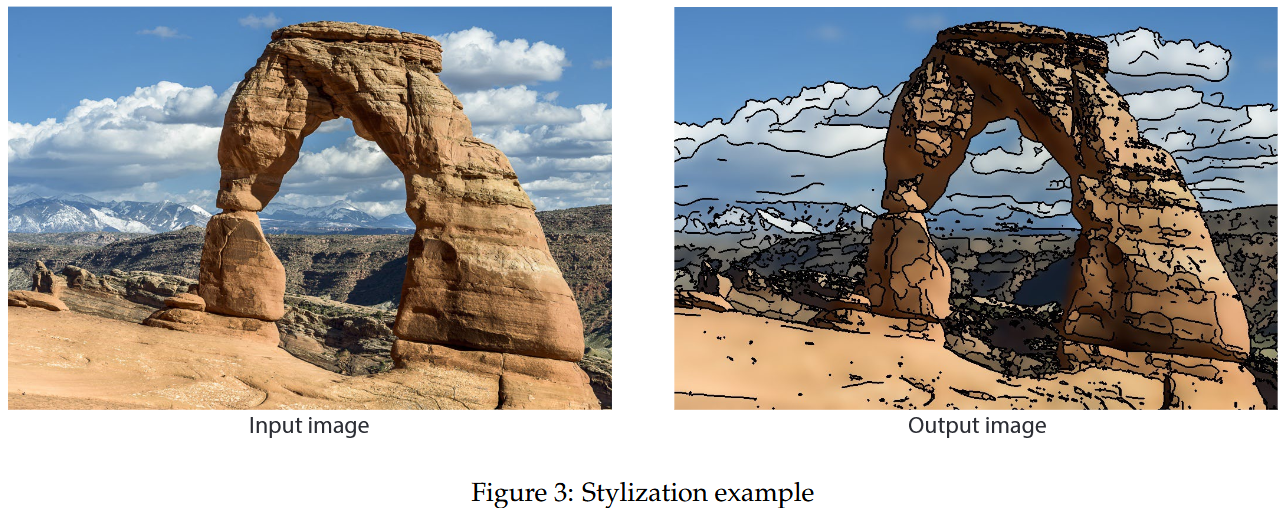

% Add your code here.

**Report.*** Add your report here.*